close all;
clear all;clc;

 t=1:0.025:5;
 desired=5*sin(2*3.*t);
 
 noise=5*sin(2*50*3.*t);
 
 refer=5*sin(2*50*3.*t+ 3/20);
 
 primary=desired+noise;
 
 subplot(4,1,1);
 plot(t,desired);
 ylabel('desired');
 
 
subplot(4,1,2);
 plot(t,refer);
 ylabel('refer'); 
 
 
 
 subplot(4,1,3);
 plot(t,primary);
 ylabel('primary');
 
  
 
 order=2;
 mu=0.005;
 n=length(primary)

n = 161

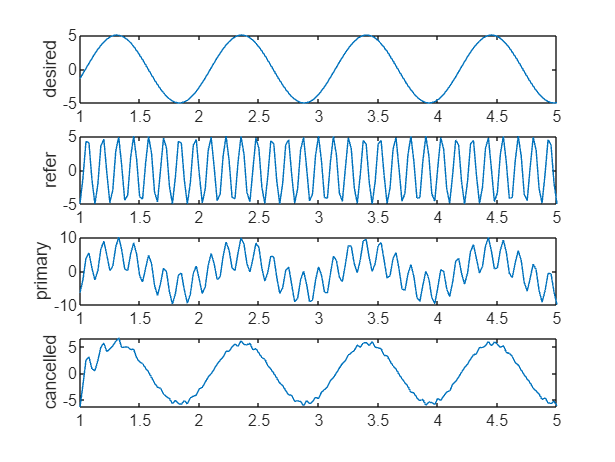

 delayed=zeros(1,order);
 adap=zeros(1,order);
 cancelled=zeros(1,n);
 
 for k=1:n,
     delayed(1)=refer(k);
     y=delayed*adap';
     cancelled(k)=primary(k)-y;
     adap = adap + 2*mu*cancelled(k) .* delayed;
     delayed(2:order)=delayed(1:order-1);
 end
 
 subplot(4,1,4);
 plot(t,cancelled);
 ylabel('cancelled');